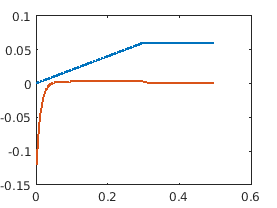

clc; clear all; close all;

R = 200; % Ohm
C = 60*10^-6; % Farad
U_s = 12; % V

simTime = 0.5; % s
rampTime = 0.3; % s

uC = 24; % V

t = 0; % s
dt = 10^-3; % s
idx = 1; % Index

while t <= simTime

    if(t <= rampTime)
        uA = U_s * t/rampTime;
    else
        uA = U_s;
    end

    i_1 = uA/R;
    i_2 = (uA-uC)/R;

    uCDot = 1/C * i_2;

    t_plot(idx) = t;
    i_1_plot(idx) = i_1;
    i_2_plot(idx) = i_2;
    uC_plot(idx) = uC;

    % Time Integration
    uC = uC + uCDot * dt;

    % Updating time and index
    t = t + dt;
    idx = idx + 1;

end

plot(t_plot, i_1_plot, 'LineWidth', 2)
hold on
plot(t_plot, i_2_plot, 'LineWidth', 2)
hold off

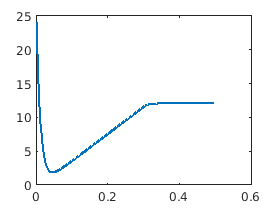

plot(t_plot, uC_plot, 'LineWidth', 2)